clear all
close all
clc

## Data Initialization

table_enzo = readtable("Enzo/Enzo_12_09_2023_PM.csv");
table_matilde = readtable("Matilde/Matilde_13_09_2023_AM.csv");

speed_enzo = table2array(table_enzo(:,5));
speed_matilde = table2array(table_matilde(:,5));

power_enzo = table2array(table_enzo(:,6));
power_matilde = table2array(table_matilde(:,6));

cadence_enzo = table2array(table_enzo(:,3));
cadence_matilde = table2array(table_matilde(:,3));

time_enzo = (1:size(power_enzo))';
time_matilde = (1:size(power_matilde))';

average_power_enzo = mean(power_enzo)

average_power_enzo = 106.7380

average_power_matilde = mean(power_matilde)

average_power_matilde = 107.0087


dev_enzo = std(power_enzo)

dev_enzo = 19.4531

dev_matilde = std(power_matilde)

dev_matilde = 26.8088


max_v_enzo = max(speed_enzo)

max_v_enzo = 80.2800

max_v_matilde = max(speed_matilde)

max_v_matilde = 75.1430

## Data visualization

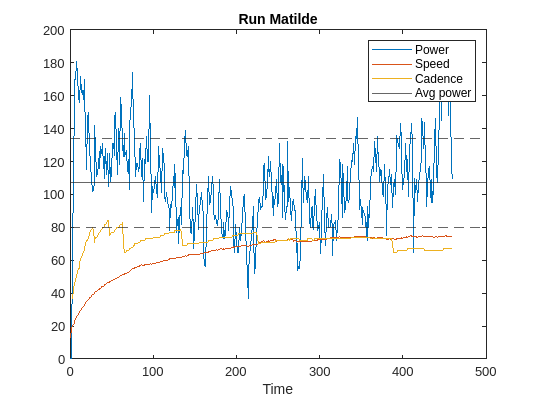

figure
plot(time_matilde,power_matilde,time_matilde,speed_matilde,time_matilde,cadence_matilde);
title("Run Matilde");
xlabel("Time");
yline(average_power_matilde);
yline(average_power_matilde-dev_matilde,"--");
yline(average_power_matilde+dev_matilde,"--");
legend("Power","Speed","Cadence","Avg power");

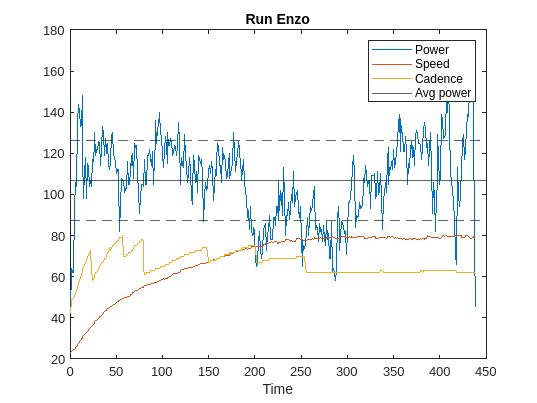


figure
plot(time_enzo,power_enzo,time_enzo,speed_enzo,time_enzo,cadence_enzo);
title("Run Enzo");
xlabel("Time");
yline(average_power_enzo);
yline(average_power_enzo-dev_enzo,"--");
yline(average_power_enzo+dev_enzo,"--");
legend("Power","Speed","Cadence","Avg power");